# Operaciones útiles con la toolbox de imágenes 

## Perfil de intensidad. 

El comando *improfile* calcula y traza las intensidades a lo largo de una línea o path en una imagen. Se pueden facilitar las coordenadas de una línea o líneas como argumentos de entrada, o se puede definir el path deseado con el ratón. En cualquier caso, improfile utiliza la interpolación para determinar los valores de los puntos igualmente espaciados a lo largo del path.

Para una línea simple, improfile traza los valores de la intensidad en dos dimensiones. Para un path múltiple, improfile traza los valores de la intensidad en tres dimensiones. 

Si se llama a improfile sin argumentos, el cursor cambia a una cruz cuando se encuentra sobre la imagen. Se puede entonces definir segmentos de línea como se muestra a continuación: 

- Para ratones de un botón seleccione los extremos de la línea presionando el botón. Para finalizar presionar Shift y botón a la vez, o pulsar Return. 

- Para ratones de dos o tres botones, seleccione los extremos de la línea presionando el botón izquierdo. Para finalizar presionar botón derecho o pulsar Return. 

La función improfile puede devolver las coordenadas de distintos puntos por los que pasan las líneas (x,y), las intensidades de los mismos (c), y las coordenadas de los extremos de los segmentos definidos (xi,yi). Para visualizar los resultados se puede utilizar plot3(x,y,c). El siguiente ejemplo visualiza la imagen spine y una muestra del trazado de intensidad a lo largo de una línea de dicha imagen con el comando improfile.*improfile*.

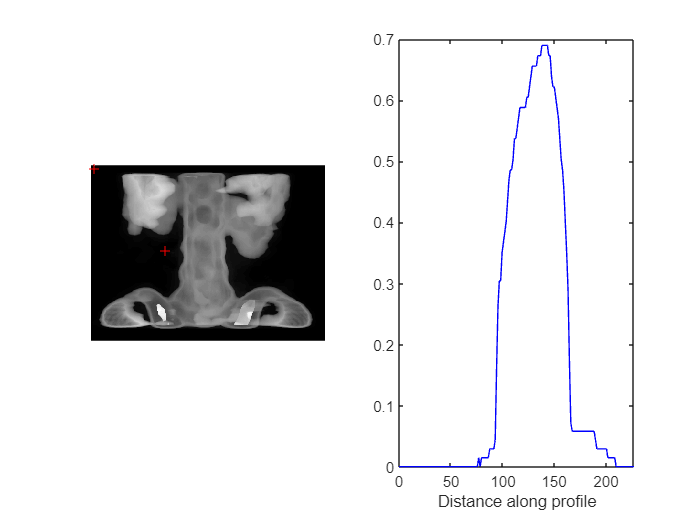

load spine % Imagen indexada de matlab guardada en variables X y map
I=ind2gray(X,map);   % I es una imagen de intensidad double entre 0 y 1
figure, subplot(1,2,1), imshow(I);
%Sobre dibujo imagen anterior pinto cruz en puntos (x1,y1)=(7,8) y (x2,y2)=(156,179)
hold on, plot([7 156],[8 179],'r+');
%Pinta los niveles de gris (intensidad) de la linea entre (x1,y1)=(7,8) y (x2,y2)=(156,179)
subplot(1,2,2), improfile(I,[7  156],[8 179])

En la última línea de código anterior, el primer corchete contiene las coordenas x de los sucesivos puntos que determinan las líneas, y el segundo corchete contiene las coordenadas y, en un sistema coordenado de píxel (eje x hacia la derecha y eje y hacia abajo). 

En una imagen RGB el perfil de intensidad de los niveles R,G,B se visualizaría de igual forma, con el comando improfile:

figure, imshow .\imagenes\flowers.tif;

Error using images.internal.getImageFromFile
Cannot find the specified file: ".\imagenes\flowers.tif".

Error in images.internal.imageDisplayParseInputs (line 75)
        images.internal.getImageFromFile(common_args.Filename);

Error in imshow (

improfile; %Seleccione con el raton puntos extremos de linea a ver perfil de intensidad

## Selección de píxeles. 

El comando impixel obtiene el valor del color del píxel seleccionado o de un conjunto de píxeles. Sin parámetros de entrada, impixel permite usar el ratón para seleccionar puntos con el botón izquierdo. Cuando se pulsa Return o el botón derecho, se añade el último punto y se devuelve el valor del color de estos en una matriz mx3. Con las coordenadas de los píxeles como entrada, impixel retorna una lista de valores de color para los puntos dados. Por ejemplo: 

load clown
vals=impixel(X,map,[231 35],[122 50]) %impixel(X,map,[x1 x2 ...],[y1 y2 ...])
% En vals devuelve los valores R,G,B de los pixeles seleccionados
%   vals =             0.1250             0                0
%                         0.8672         0.4141            0

## Barra de color.

El comando *colorbar* añade una barra de color a cualquier eje. Las barras de color relacionan los colores en una imagen con valores físicos, tal como la temperatura. Aquí se muestra un uso típico de colorbar. 

load trees
I=ind2gray(X,map);
F=fftshift(fft2(I));
figure, imagesc(log(abs(F)));colorbar,colormap(jet)

La función colorbar funciona para cualquier tipo de trazado, y puede situar la barra de color tanto horizontal como verticalmente. Sin argumentos, colorbar actualiza una barra de color existente.

## Fusionar imágenes.

El comando *imfuse *sirve para fusionar imágenes.

A=imread(".\imagenes\circles.tif");
imshow(A);
B=imread(".\imagenes\rice.jpg");
imshow(B);
C=imfuse(A,B, 'blend');
imshow(C);